# Fear the false negative: How to correctly report and interpret a "non-significant" result.

Author: Ross Wilkinson

Affiliation: University of Colorado

Date: 26-Dec-2020

Often I see studies that proclaim "there no difference between condition A and B" despite there study being underpowered to detect the effect size that was present between the two conditions. It is important that authors begin to acknowledge the presence of small effect sizes and that their result may be a false negative. Here I present an example from a recently published study where the false negative risk should have been acknowledged. These authors aren't alone, I too have made this mistake in the past. My hope is that beginning to shine a light on this false inference will increase awarness and decrease its prevalence in peer-reviewed publications. It is also possible that the methods I present here could be of use for providing evidence for or against  effect sizes being present in the long run.

The data used in this example have been recreated from the following publication using WebPlot Digitizer 4.2.

Merkes, Paul F.J., Paolo Menaspà, and Chris R. Abbiss. 2020. “Power Output, Cadence, and Torque Are Similar between the Forward Standing and Traditional Sprint Cycling Positions.” *Scandinavian Journal of Medicine and Science in Sports* 30: 64–73.

This study compared maximal power output over a complete crank cycle generated during a 14-sec sprint by the same group of subjects (n=11) in either a traditional standing sprint posture (STA) versus a new forward standing posture (FWD).

I will discuss the following:

- the presentation of the results

- the statistical power of the study

- the statistical inference that can be drawn from the results

## The published result

Here are the group maximal power output results from the two test conditions (mean ± standard deviation).

mean_sta = 1276

mean_sta = 1276

sd_sta = 161

sd_sta = 161

mean_fwd = 1202

mean_fwd = 1202

sd_fwd = 149

sd_fwd = 149

mean_diff = mean_fwd - mean_sta

mean_diff = -74

On average, maximal power output was 74 W (5.8%) lower in FWD *versus* STA, however this did not reach statistical significance.

## The published figure

Here is a recreation of the bar graph that was used to present the results. 

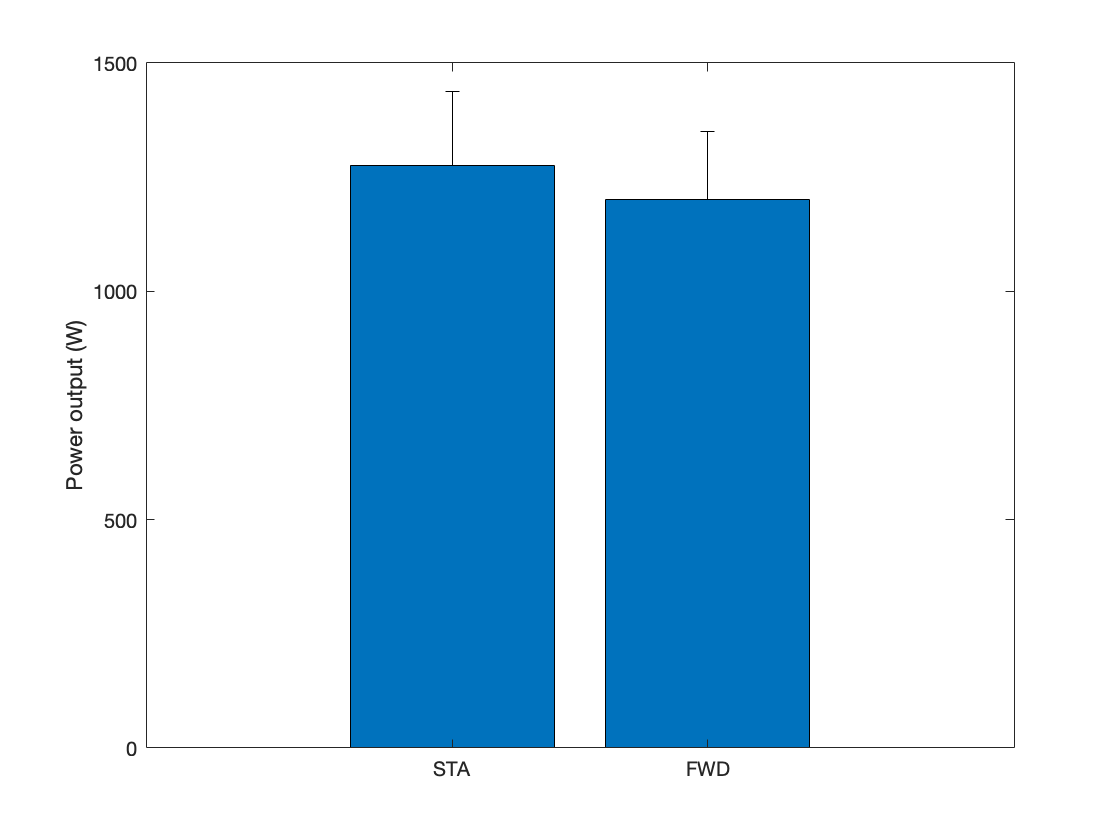

x = 1:2;
data = [mean_sta mean_fwd];
err = [sd_sta sd_fwd];
bar(x,data)
hold on
er = errorbar(x,data,[0 0],err,'k');
er.LineStyle = 'none';
ax = gca;
ax.XTickLabels = {'STA','FWD'};
ylabel('Power output (W)')
hold off

Remember that this study used a repeated-meausres design i.e. the same subject group performed both conditions. Thus, a bar graph with a standard deviation bar is not appropriate to display these results. This study is concerned with within-subject differences, which means an error bar showing the variation between subjects tells us nothing about the effect of condition within each subject. We know that, on average, power output was lower in FWD, but how consistent was this effect? Were there any outliers? We are left in the dark about what really matters when conducting a paired t-test; the mean and standard deviation of the pairwise differences.

## Recreate the STA data

Despite the lack of information provided by the authors, we can do a fairly decent job to recreate the data for each  individual. To do this we have to assume that both the maximal power output results and the pairwsie differences followed a standard normal distribution. Based on this assumption we can recreate a probability distribution for the group results and the pairwise differences, and then randomly sample from these distributions.

Create the distribution of maximal power output for the STA condition.

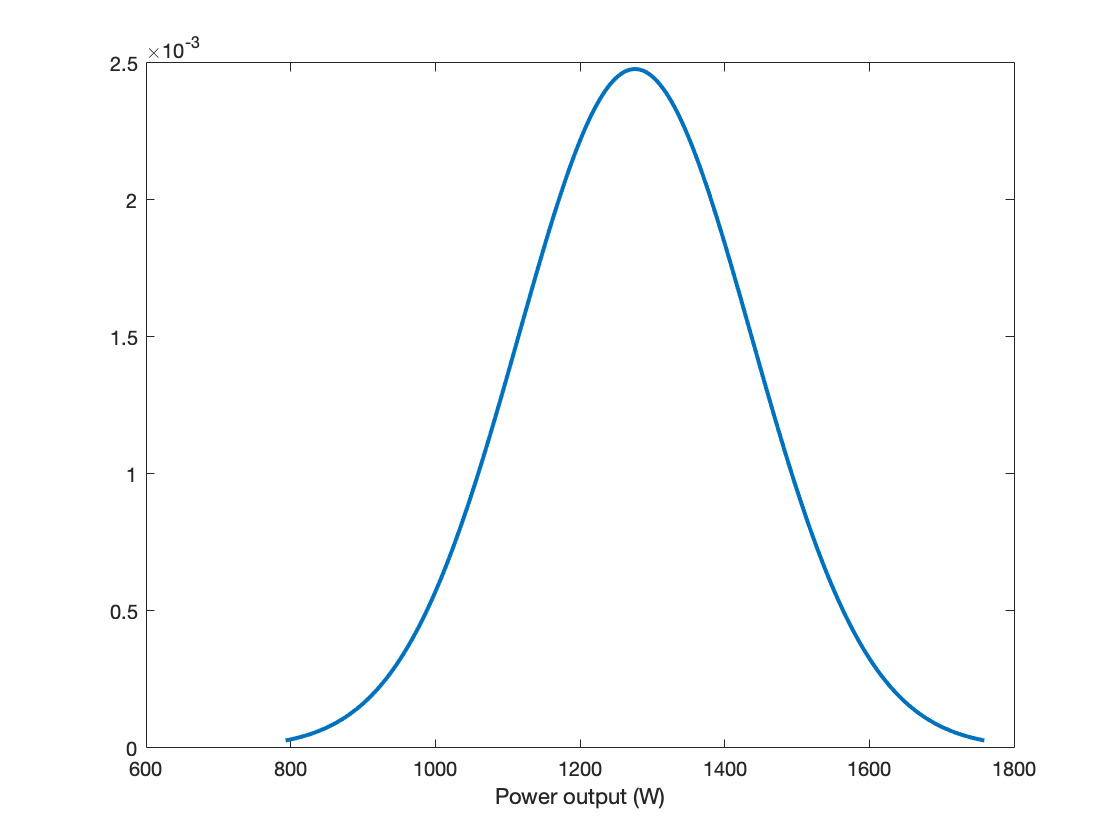

x = mean_sta-(sd_sta*3):mean_sta+(sd_sta*3);
pd_sta = makedist('Normal', ...
    'mu',mean_sta,'sigma',sd_sta);
pdf_sta = pdf(pd_sta,x);
plot(x,pdf_sta,'linewidth',2)
xlabel('Power output (W)')

## Recreate the pairwise differences

Because of the repeated-measures design, we can't just recreate the FWD group results based off the mean and standard deviation. Instead we need to recreate the pairwise differences. To do this we have to know the effect size (mean difference / standard deviation of mean differences). The authors merely report that the results did not reach statistical significance, with no mention of the p-value or effect size. So all we can do is assume that the effect size was lower than the smallest detectable effect size (SDES) of the study. We can calculate the SDES using the freely available G*Power software package.

Running a sensitivity analysis in G*Power for a paired t-test with the following inputs (two-tailed, alpha = 0.05, power = 0.9, sample size = 11) gives the following results:

- Required effect size at 90% power = 1.09

- Criticial t = 2.228

- SDES (critical t / sqrt(n)) = 0.67

Thus, this study could not detect effect sizes less than 0.67. An effect of this size would typically be classified as moderate based on the following cut-offs: 0.3 = small, 0.5 = moderate, 0.8 = large (Cohen, 1988).

So, to recreate the pairwise differences we can be confident that the effect size betwen STA and FWD was less than 0.67. We will be conservative and assume that the effect size that did not reach statistical significant in the study was 0.3 (i.e. the mean of the pairwise differences was half the standard deviation of the pairwise differences).

Create the distribution of pairwise differences between STA and FWD.

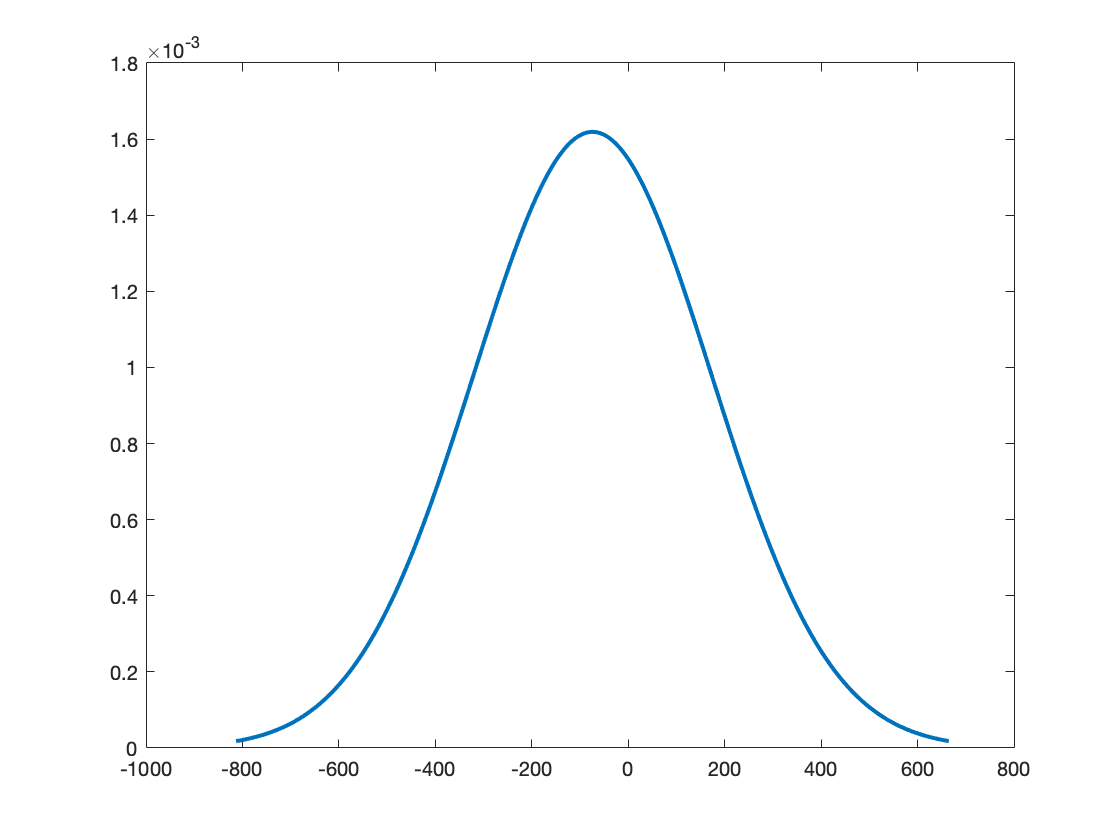

sd_diff = abs(mean_diff * 3.33);
x = mean_diff-(sd_diff*3):mean_diff+(sd_diff*3);
pd_diff = makedist('Normal', ...
    'mu',mean_diff,'sigma',sd_diff);
pdf_diff = pdf(pd_diff,x);
plot(x,pdf_diff,'linewidth',2)

## Recreate the data for each subject

Now that we have a distribution for STA and the pairwise differences we can take 11 random samples from each to recreate the data for the 11 subjects.

sta_new = random(pd_sta,11,1);
diff_new = random(pd_diff,11,1);
fwd_new = sta_new + diff_new;

Let's checkout the descriptive statistics for our randomly generated data. 

mean_sta_new = mean(sta_new)

mean_sta_new = 1.2708e+03

sd_sta_new = std(sta_new)

sd_sta_new = 161.6221

mean_fwd_new = mean(fwd_new)

mean_fwd_new = 1.2339e+03

sd_fwd_new = std(fwd_new)

sd_fwd_new = 230.8460

## Plot the individual data

Now let's take a look at the new data using a more appropriate visual display of repeated-measures data. On the left panel we will display the individual and group mean data. On the right panel we will display the mean and standard deviation of the pairwise differences.

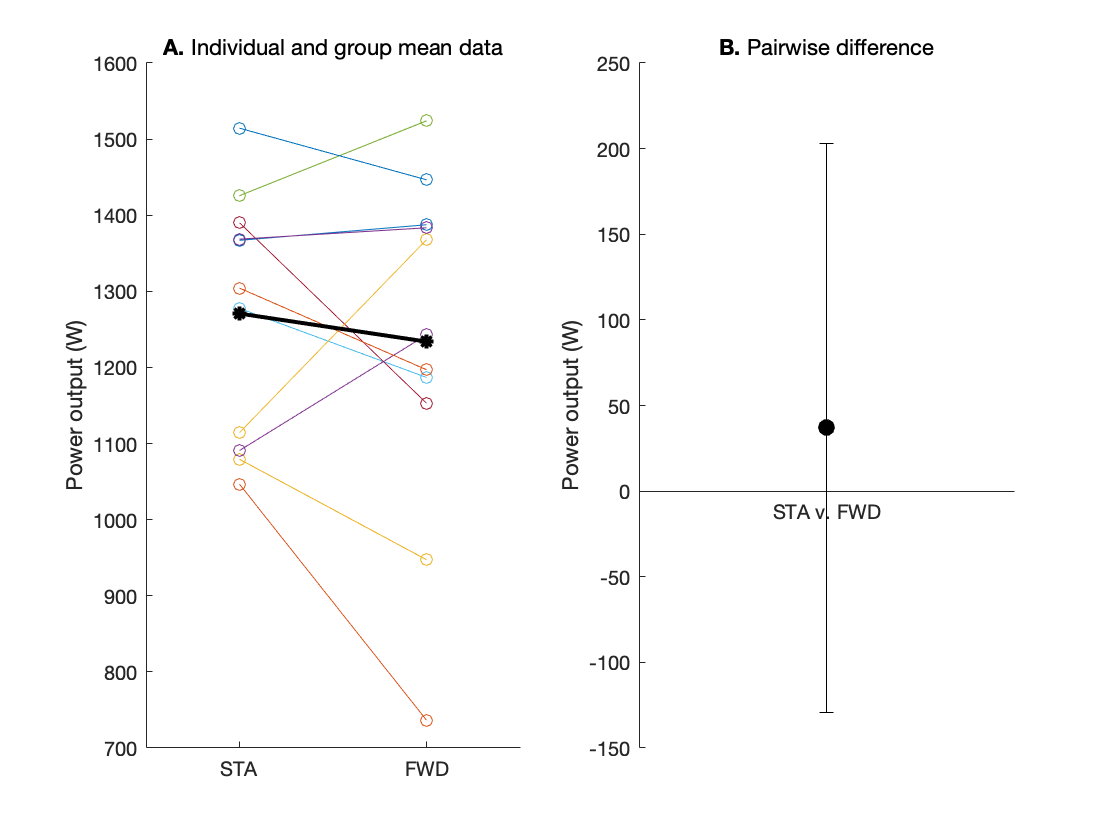

figure('color','w')
subplot(121)
plot([sta_new fwd_new]','o-')
hold on
plot([mean_sta_new mean_fwd_new],'k*-','LineWidth',2)
xlim([0.5 2.5])
box off
ylabel('Power output (W)')
ax = gca;
ax.XTick = 1:2;
ax.XTickLabel = {'STA','FWD'};
title('A. \rmIndividual and group mean data')

subplot(122)
mean_diff_new = mean(diff_new);
sd_diff_new = std(diff_new);
errorbar(1,-mean_diff_new,sd_diff_new,'ko', ...
    'MarkerSize',8, ...
    'MarkerEdgeColor','k', ...
    'MarkerFaceColor','k')
xlim([0 2])
ax = gca;
ax.XAxisLocation = 'origin';
box off
ax.XTick = 1;
ax.XTickLabel = {'STA v. FWD'};
ylabel('Power output (W)')
title('B. \rmPairwise difference')
hold off

## Statistically test the new data

[h,p,ci,stats] = ttest(sta_new,fwd_new)

h = 0

p = 0.4788

ci =   -74.8481
  148.6435


stats = struct with fields:
    tstat: 0.7357
       df: 10
       sd: 166.3356


effect_size = mean_diff_new / sd_diff_new

effect_size = -0.2218

You can see that in our new randomly generated experiment that the results are different from the publication. Hopefully you recognize that this result will change every time we resample from each distribution, thus, it is possible that the results of this one simulation do not represent the most likely outcome in the long run. To get a better idea of this we can simulate our experiment over and over again and see what the distribution of the results looks like. This should give us a better idea of whether the lack of significance in the published study represents what is likely to be the true effect size.

## Simulate the experiment 10,000 times

For each paired t-test, we will draw random samples of 11 from the STA and pairwise difference distributions. We then repeat this 10,000 times. What we are interested in is the distribution of p-values and effect sizes across our 10,000 simluations. This should give us a better understanding of the difference in power output between the two conditions.

[rho, es, mean_sta_sim, mean_fwd_sim, ...
    mean_diff_sim] = deal(NaN(10000,1));
for i = 1:10000
    sta_sim = random(pd_sta,11,1);
    diff_sim = random(pd_diff,11,1);
    fwd_sim = sta_sim + diff_sim;
    [h,p,ci,stats] = ttest(sta_sim,fwd_sim);
    rho(i) = p;
    es(i) = mean(diff_sim) / std(diff_sim);
    mean_sta_sim(i) = mean(sta_sim);
    mean_fwd_sim(i) = mean(fwd_sim);
    mean_diff_sim(i) = mean(diff_sim);
end

## The Long Run

Plot the distribution of p-values, effect sizes, mean values for each group, and the mean pairwise differences.

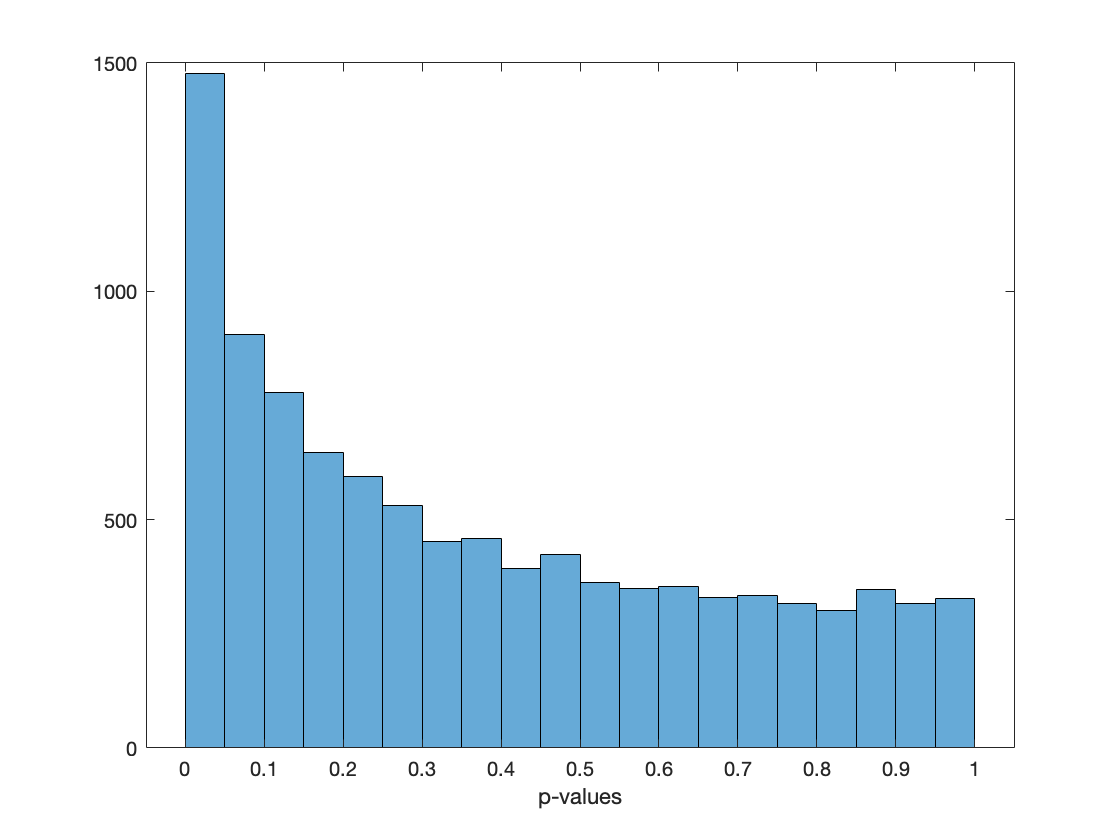

figure
histogram(rho,20)
xlabel('p-values')

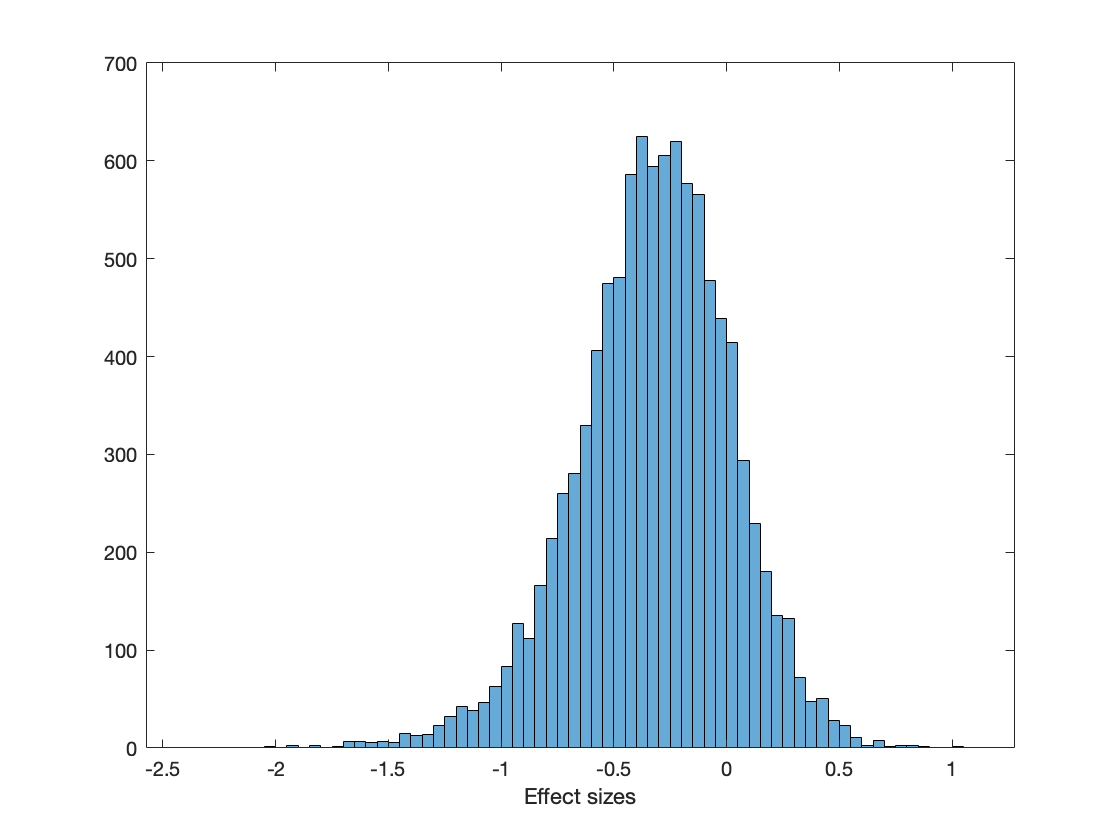

figure
histogram(es)
xlabel('Effect sizes')

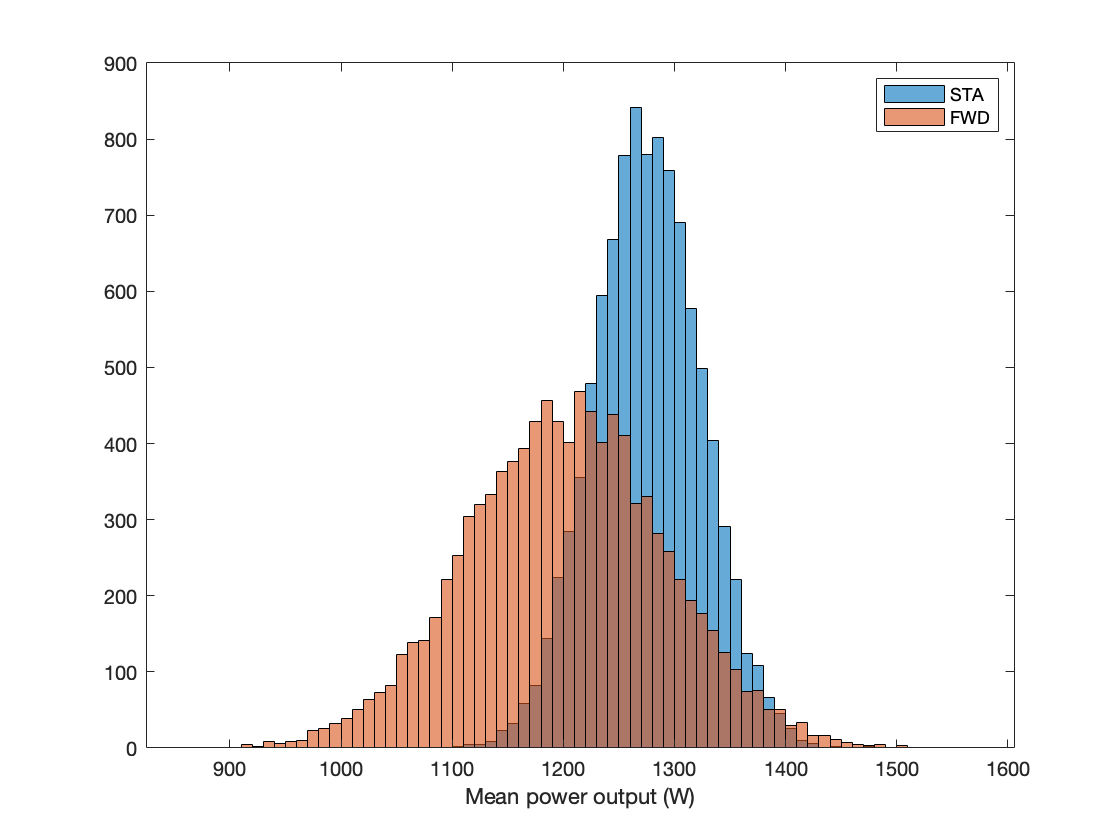

histogram(mean_sta_sim)
hold on
histogram(mean_fwd_sim)
legend('STA','FWD')
xlabel('Mean power output (W)')
hold off

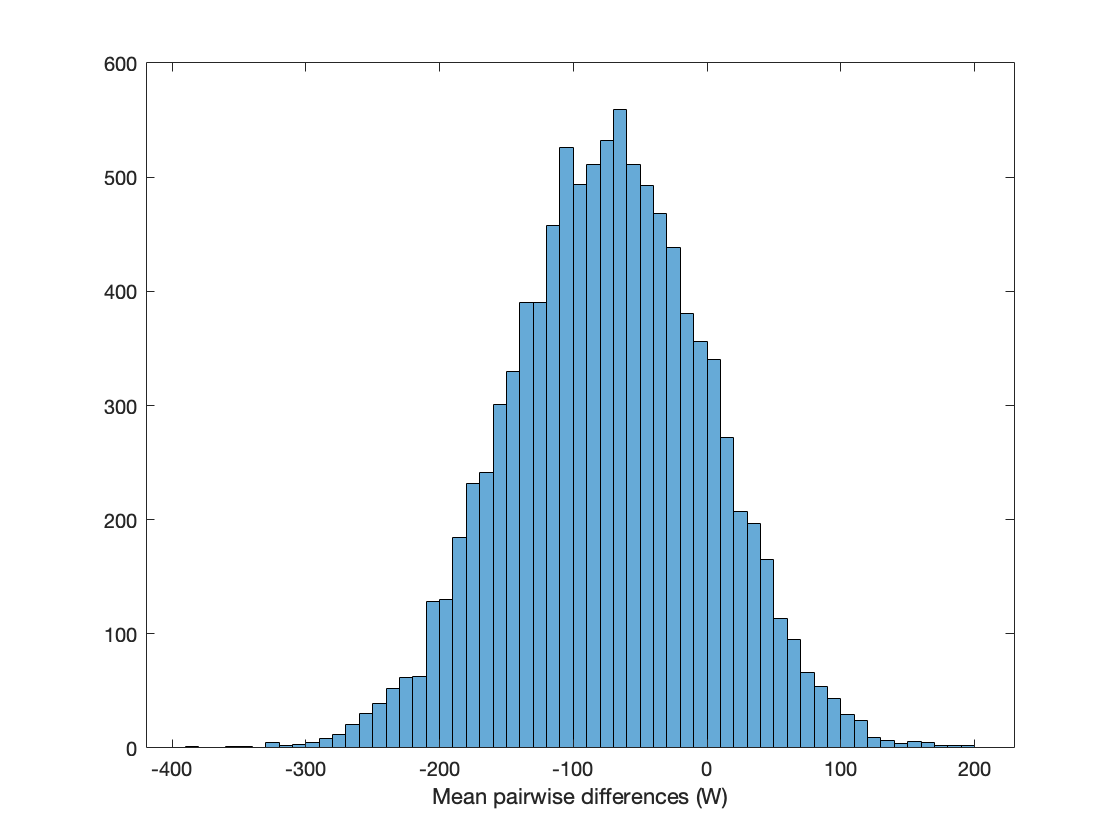

histogram(mean_diff_sim)
xlabel('Mean pairwise differences (W)')

Print the mean values over 10,000 simulations

mode_sim_p = mode(round(rho,2))

mode_sim_p = 0.0100

mean_sim_es = mean(es)

mean_sim_es = -0.3235

mean_sim_sta = mean(mean_sta_sim)

mean_sim_sta = 1.2757e+03

mean_sim_fwd = mean(mean_fwd_sim)

mean_sim_fwd = 1.2025e+03

mean_sim_diff = mean(mean_diff_sim)

mean_sim_diff = -73.2748

## Conclusion

You can see that in the long run the most common outcome is a statistically significant results (p=0.01) with an average effect size of 0.3. This could be due to our assumption that the mean differences follow a standard normal distribution. However, it seems that even with a sample size (n=11) that is underpowered to detect an effect size of 0.3—in the long run—the highest probability outcome is a statistically significant effect size of 0.3. 

I recommend that authors always report the effect size and p-value regardless of their magnitude. It is important for authors to recognize the smallest effect size that their study is capable of detecting, which can easily be calculated using G*Power. It is also important for authors to acknowledge the false positive and false negative risk associated with their decision to accept or reject the null and to word their inference accordingly. I recommend the use of the term "inconclusive" rather than "not significantly different" because the latter implies to the reader the incorrect assumption that no effect exists.